clear all
clc
addpath('./utils/')
addpath('./Realization')
addpath('./MPC')

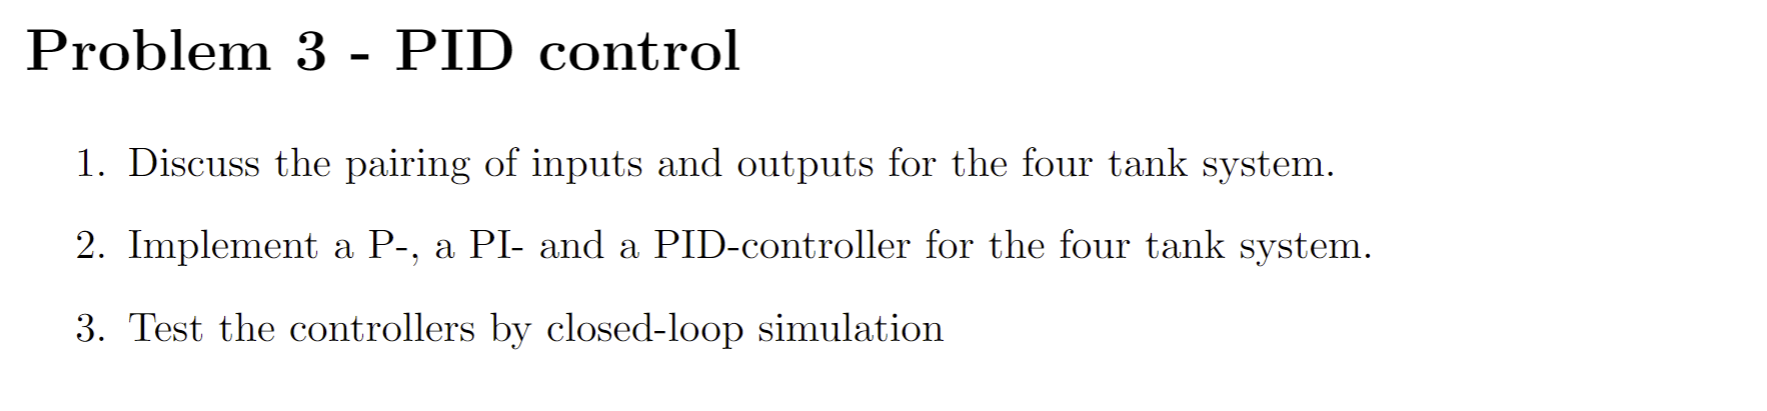

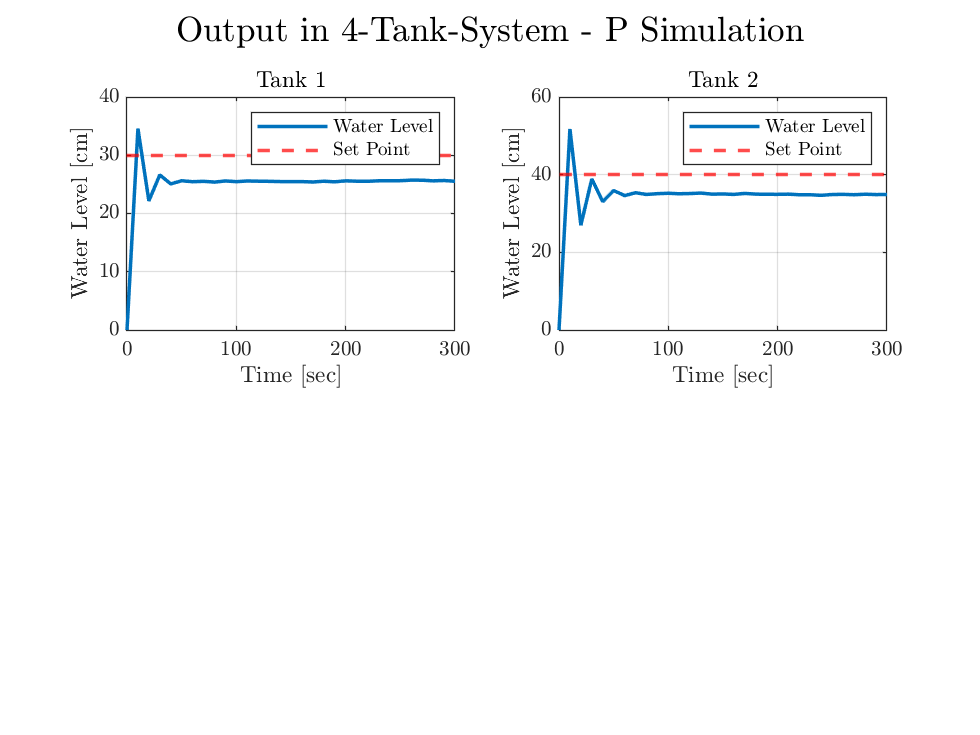

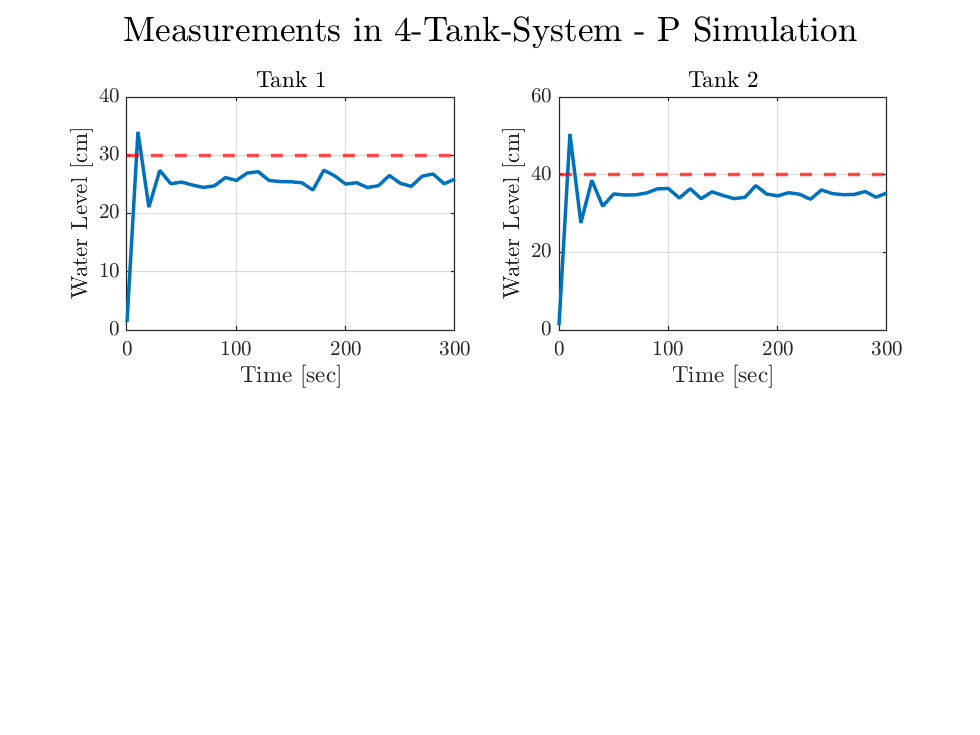

parameters = param();

t0 = 0.0;
tfin = 5*60;
Ts = 10;
t = [t0:Ts:tfin];     % time vector
N = length(t);

sz = 4;
su = 2;

% Realization of Ns Standard Brownian Motions
Ns = 2;            % Number of realizations
seed = 100;         % Seed for reproducibility
rng(seed);
dV = sqrt(Ts)*randn(Ns,N); 
d_s = cumsum(dV,2);



% Measurement Noise setup
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);


nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);

% Process noise
Q = [2 1; 1 10];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);



z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
step_size = 0.01;
x(:,1) = [0;0;0;0];
% Define period and amplitude of the square waves
period = 30;       % Length of one period of the square wave
amplitude = 25;     % Amplitude of the square wave

for i = 1:period:N
    if mod(i, 2*period) < period
        d(:, i:min(i+period-1, N)) = 2*amplitude;
    else
        d(:, i:min(i+period-1, N)) = amplitude;
    end
end


%% Set points
z1 = 30; % Set point for tank 1
z2 = 40; % Set point for tank 2

% Proportional, Integral, and Derivative gains for each controller
Kp = [50; 55]; % kp1, kp2
Ki = [0; 0]; % ki1,ki2
Kd = [0; 0]; % kd1, kd2

% Initialize variables
integral_error = zeros(2, 1); % Integral of the error for each tank
previous_error = zeros(2, 1); % Previous error for derivative term for each tank
u = zeros(2, N); % Control inputs for F1 and F2

for k = 1:N-1

    y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function WITH noise 
    z(:,k) = FourTankSystemOutput(x(:,k),parameters);

    % Calculate error between set points and actual water levels
    error = [z1; z2] - z(:, k);
    
    % Update integral of the error
    integral_error = integral_error + error * Ts;
    
    % Calculate derivative of the error
    derivative_error = (error - previous_error) / Ts;
    
    % PID control law for each tank
    u(:, k)  = Kp .* error + Ki .* integral_error + Kd .* derivative_error;
    
    disturbance = d(:,k) + d_s(:,k);
    [Tk,Xk] = ode45(@ModifiedFourTankSystem,[t(k):step_size:t(k+1)],x(:,k),[], ...
        u(:,k)+ w(:,k),disturbance,parameters);
    x(:,k+1) = Xk(end,:)';
    X = [X; Xk];
    % Update previous error
    previous_error = error;
end

y(:, N) = FourTankSystemSensor(x(:, N), parameters) + v(:, N);
z(:, N) = FourTankSystemOutput(x(:, N), parameters);

y = y(1:2,:);

plotting_pid(t, z', y', [z1; z2],' P Simulation');

%plotting_pid(T, H, Qout, set_points, rise_times, overshoots, name)

%plotting(t, z', y', "SDE with Noise and Disturbance");
%plotting(T, H, Qout, name)
